# Signal after MAX2771

%rawdata = randi([0 1], [1 50e3]); 
%rawdata = [1 0 1 1 0 0 1 0 0 1 1 0 0 1 1];
rawdata = repmat([1 0 1 0 0 1 1 0 1 0],1,30);
%rawdata = repmat([1 1 1 1 1 1 1 1 1 1],1,30);

fca     = 1.023e6;          % C/A code frequency
%fc      = 1575.42e6;        % Carrier frequency
fs      = 20*fca;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) 
%                               spreading code rate n*1.023 MHz
codeLength = round(1023/n); 

fdoppler = [1010, 3425, -280,0];
ca_codes = [ 1,  8,  20, 12];
code_phase = [200, 30, 834, 514];

% Rsignal = 2*( ...
%              .25*Received_Simplified(rawdata,fca,fs,fdoppler(1) ...
%              ,ca_codes(1),1,code_phase(1)) + ...
%            ...
%            .25*Received_Simplified(rawdata,fca,fs,fdoppler(2), ...
%            ca_codes(2),1,code_phase(2)) + ...
%            ...
%            .25*Received_Simplified(rawdata,fca,fs,fdoppler(3), ...
%            ca_codes(3),1,code_phase(3)) + ...
%            ...
%            .25*Received_Simplified(rawdata,fca,fs,fdoppler(4), ...
%            ca_codes(4),1,code_phase(4)));

%Rsignal = 4*(.25*Received_Simplified(rawdata,fca,fs, ...
%               fdoppler(1),ca_codes(1),1,0) + ...
%            .25*Received_Simplified(rawdata,fca,fs, ...
%               fdoppler(4),ca_codes(4),1,514));

Rsignal = 2*(Received_Simplified(rawdata,fca,fs, ...
              fdoppler(1),ca_codes(1),1,code_phase(1)));

[I,Q, clk] = MAX2771_simplified(Rsignal, fs, round(2), true);

clear Rsignal;

## Defining the PLL tracking loop

IQ = I + 1i*Q;

gc_full = data_mapper(gold_code_L1(codeLength,1));
gc_full = expand(gc_full,20*length(rawdata));
gc_full = upsampler(gc_full,length(IQ)/length(gc_full));
gc_length = length(gc_full);

code_nco = code_phase(1)*10*.985;
cd_phase = round(code_nco);

spacing = length(IQ)/(2*20*length(rawdata)*1023);
block_size = length(IQ)/(20*length(rawdata));

[IE, QE, IP, QP, IL, QL] = deal(zeros(1,length(IQ)/block_size));

omega_init = fdoppler(1)-10;
omega = omega_init;

T_PID = block_size/clk;
filt_I_PLL = 0;
Kp_PLL = 10;
Ki_PLL = 1;
Kd_PLL = .5;

IQ_data = zeros(1,length(IQ));
nco_out = zeros(1,length(IQ));
pd_out = zeros(1,length(IQ)/block_size);
phase_acc = 0;
phase_ramp = 0;
delta_omega = zeros(1,length(IQ)/block_size);
local_time_idx = 0:(block_size-1);

% Filtro do DLL a ser ajustado
filt_I_DLL = 0;
Ki_DLL = 2;
Kp_DLL = 4;
Kd_DLL = 1;
cd_out = zeros(1,length(IQ)/block_size);
DLL_filter = zeros(1,length(IQ)/block_size);
ca_phase_rec = zeros(1,length(IQ)/block_size+1);
ca_phase_idx = zeros(1,length(IQ)/block_size+1);

ca_phase_rec(1) = code_nco;
ca_phase_idx(1) = cd_phase;

for i = 1:length(IQ)/block_size
    idx = (1:block_size) + (i - 1) * block_size;

    phase_ramp = phase_acc + ...
        2.*pi.*omega(i)*local_time_idx./clk;
    nco_out(idx) = exp(-1i.*phase_ramp);

    phase_acc = mod(phase_ramp(end) ...
          + 2*pi*omega(i)/clk,2*pi);

 % Índices para Prompt, Early e Late (com modularidade)
    prompt_idx = mod((0:block_size-1) - cd_phase, gc_length) + 1;
    early_idx  = mod(prompt_idx - spacing - 1, gc_length) + 1;
    late_idx   = mod(prompt_idx + spacing - 1, gc_length) + 1;
   
    % Códigos PRN deslocados
    gc_p = gc_full(prompt_idx);
    gc_e = gc_full(early_idx);
    gc_l = gc_full(late_idx);

    corr_E = IQ(idx) .* gc_e .* nco_out(idx);
    corr_P = IQ(idx) .* gc_p .* nco_out(idx);
    corr_L = IQ(idx) .* gc_l .* nco_out(idx);

    IE(i) = sum(real(corr_E))/block_size;
    QE(i) = sum(imag(corr_E))/block_size;
    IP(i) = sum(real(corr_P))/block_size;
    QP(i) = sum(imag(corr_P))/block_size;
    IL(i) = sum(real(corr_L))/block_size;
    QL(i) = sum(imag(corr_L))/block_size;
    mag(i) = sqrt(IP(i)^2 + QP(i)^2);
    
    % FIXED: Store and use the current error immediately at index (i)
    current_error = pd(IP(i), QP(i));
    pd_out(i) = current_error;
    
    % FIXED: Integrator now uses the current_error without a 1-block delay
    if i == 1
        filt_I(i+1) = Ki_PLL * current_error;
        filt_D = 0;
    else
        filt_I(i+1) = Ki_PLL * current_error + filt_I(i);
        filt_D = Kd_PLL * (current_error - pd_out(i-1));
    end    
    
    % FIXED: All terms now use the synchronized current tracking states
    d_omega = Kp_DLL * current_error + filt_I(i+1) + filt_D;
    delta_omega(i) = d_omega;
    
    omega(i+1) = omega_init + delta_omega(i);

    cd_out(i+1) = code_discriminator(IE(i),QE(i), ...
        IP(i),QP(i), IL(i),QL(i));
    
    filt_I_DLL = Ki_DLL*cd_out(i+1) + filt_I_DLL;
    filt_D_DLL = Kd_DLL*(cd_out(i+1)-cd_out(i));
    DLL_filter(i) = Kp_DLL*cd_out(i+1) + filt_I_DLL + filt_D_DLL;
    
    code_nco = code_nco + DLL_filter(i);
    cd_phase = round(code_nco);
    ca_phase_rec(i+1) = code_nco;
    ca_phase_idx(i+1) = cd_phase;
end
cd_omega = omega(end)

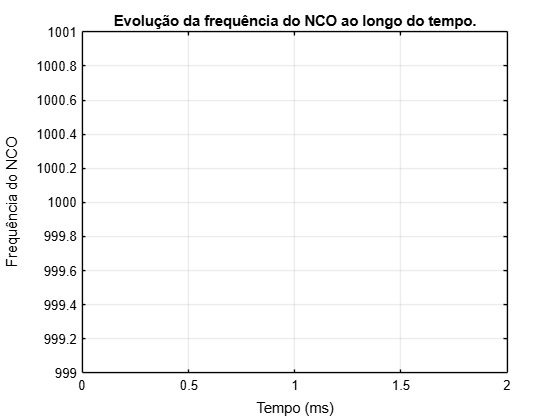

figure('Name','Evolução do erro de frequência do NCO ao longo do tempo',...
    'Color','w'); 

plot(omega);
ax = gca;

ax.Color = 'w';        % fundo da área do gráfico
ax.XColor = 'k';       % eixo X preto
ax.YColor = 'k';       % eixo Y preto
ax.GridColor = [0.7 0.7 0.7];

set(gca,'Color','w');
xlabel('Tempo (ms)');
ylabel("Frequência do NCO");
grid on;
title("Evolução da frequência do NCO ao longo do tempo.", "Color",'k');

hold on


erro_omega = abs(fdoppler(1) - omega);
limite_omega = 0.02*erro_omega(1);
janela = 100; % 100 amostras = 100 ms
idx_conv_omega = NaN;
for k = 1:length(erro_omega)-janela

    if all(erro_omega(k:k+janela) <= limite_omega)
        idx_conv_omega = k;
        break
    end

end
tempo_conv_omega = idx_conv_omega; % 1 amostra = 1 ms

% ponto de convergência
plot(idx_conv_omega,...
     omega(idx_conv_omega),...
     'ro',...
     'MarkerSize',10,...
     'LineWidth',2)

Array indices must be positive integers or logical values.


% linha vertical
xline(idx_conv_omega,...
      '--k',...
      sprintf('Convergência = %d ms',tempo_conv_omega),...
      'LineWidth',1.5,...
      'FontSize',10,...
      'LabelOrientation','horizontal');

exportgraphics(gcf,'Rastreio_PLL.png',...
    'BackgroundColor','white',...
    'Resolution',300);

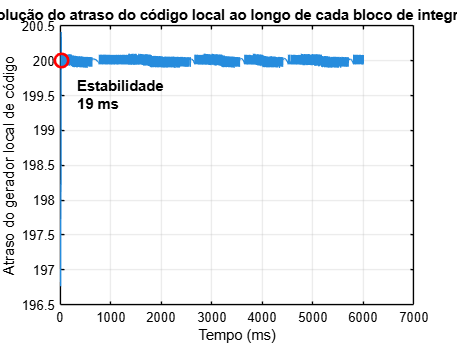

figure('Name','Evolução do atraso estimado pela DLL ao longo do tempo',...
    'Color','w'); 

plot(ca_phase_rec/10);

ax = gca;
ax.Color = 'w';        % fundo da área do gráfico
ax.XColor = 'k';       % eixo X preto
ax.YColor = 'k';       % eixo Y preto
ax.GridColor = [0.7 0.7 0.7];

set(gca,'Color','w');

xlabel('Tempo (ms)');
ylabel("Atraso do gerador local de código")
grid on;
title("Evolução do atraso do código local ao longo de cada bloco de integração.", "Color",'k');

hold on

erro_cd = abs(code_phase(1) - ca_phase_rec/10);
erro_inicial_cd = erro_cd(1);
limite_cd = 0.02*erro_inicial_cd; % 2%
idx_conv_cd = find(erro_cd <= limite_cd,1,'first');
tempo_conv_cd = idx_conv_cd; % 1 amostra = 1 ms

plot(idx_conv_cd,...
    ca_phase_rec(idx_conv_cd)/10,...
    'ro',...
    'MarkerSize',10,...
    'LineWidth',2)

text(idx_conv_cd + 300,...
    ca_phase_rec(idx_conv_cd)/10 - .5,...
    sprintf('Estabilidade\n%.0f ms',tempo_conv_cd),...
    'Color','k',...
    'FontSize',11,...
    'FontWeight','bold')


exportgraphics(gcf,'Rastreio_DLL.png',...
    'BackgroundColor','white',...
    'Resolution',300);

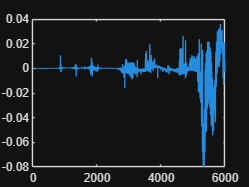

figure; plot(DLL_filter);

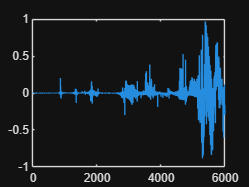

figure; plot(cd_out);

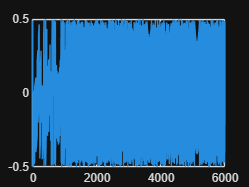

figure; plot(pd_out)

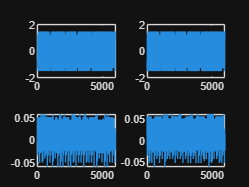

figure
subplot(2,2,1)
plot(IE)
subplot(2,2,2)
plot(IL)
subplot(2,2,3)
plot(QE)
subplot(2,2,4)
plot(QL)

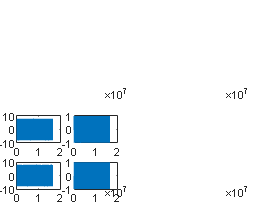

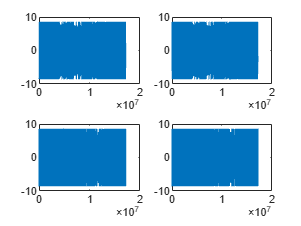

close all;

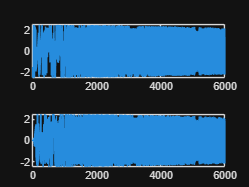

figure;
subplot(2,1,1)
plot(IP)
subplot(2,1,2)
plot(QP)

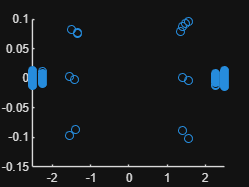

figure
scatter(IP,QP)

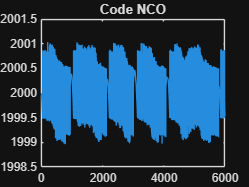

figure
plot(ca_phase_rec)
title('Code NCO')

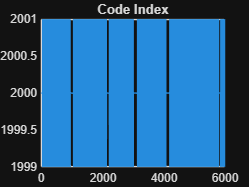


figure
plot(ca_phase_idx)
title('Code Index')